# **Geostatistika 8**

### **Otázky**

Pracuji-li v MATLAB s náhodnými čísly, tak pokud nastavím před příklady stejný *seed*, pak bys nad měla být sekvence reprodukovatelná tzn. dostanu stený čísla jako někdo přede mnou. Je to pravda a správný postup?

Zdá se mi, že některé funkce, které dělají graf uvnitř cyklu běží hrozně dlouho pro velká n, např `randwalk`. Často se mi úplně zasekne MATLAB. Může to být tím?

### **Úkol 1.    Rovnoměrné rozdělení**

Náhodná proměnná X je rovnoměrné rozdělená, pokud každý hodnota  této náhodné proměnné má stejnou pravděpodobnost, že nastane při opakování pokusu. Z histogramů je vidět, že pro zvyšující se počet pokusů, se četnosti v jednotlivých jednotlivých náhodně generovaných čísel přibližují. Příklad: Pokud bychom házeli kostkou, tak pro diskrétní náhodnou proměnnou *padnutí čísla* s možnými hodnotami 1, 2, 3, 4, 5, 6, se bude spolu s rostoucí hodnotou `n `frekvence padnutí každého z čísel blížit stejné hodnotě.

seed = 3;
rng(seed);
xs = zeros(100);

Definovak jsem tuto funkci v samostatném souboru, kterou používám pro vykreslení.

Pokus pro $n = 100$.

n = 100;

% 1. náhodný výběr pro n = 100.
randomPoints1DUniform(n, 3);
% 2. náhodný výběr pro n = 100.
randomPoints1DUniform(n, 3);
% 3. náhodný výběr pro n = 100.
randomPoints1DUniform(n, 3);

Pokus pro $n = 1000$.

n = 1000;

% 1. náhodný výběr pro n = 1000.
randomPoints1DUniform(n, 3);
% 2. náhodný výběr pro n = 1000.
randomPoints1DUniform(n, 3);
% 3. náhodný výběr pro n = 1000.
randomPoints1DUniform(n, 3);

Pokus pro $n = 10000$.

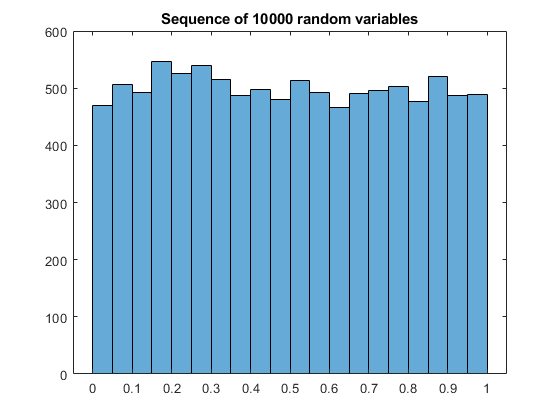

n = 10000;

% 1. náhodný výběr pro n = 10000.
randomPoints1DUniform(n, 3);

### **Úkol 2.    Normální rozdělení**

Normálni rozdělení je se označuje jako $N(\mu, \sigma^2)$, kde $\mu$ a $\sigma^2$ jsou parametry Gaussovy distrtibuční funkce. Pokud je náhodná proměnná ditribuována podle této funkce, pak o ní říkáme že je normálně rozdělená, proto to $N$. Pro různé volby $\mu$ a $\sigma^2$ dostaneme různé tvary této funkce.

**A)**

for n = [10, 100, 10000]
    x = randn(1, n);
    sprintf('n=%d mean=%f', n, mean(x));
    sprintf('n=%d var=%f' , n, var(x));
    sprintf('n=%d std=%f' , n, std(x));
end

**B) **

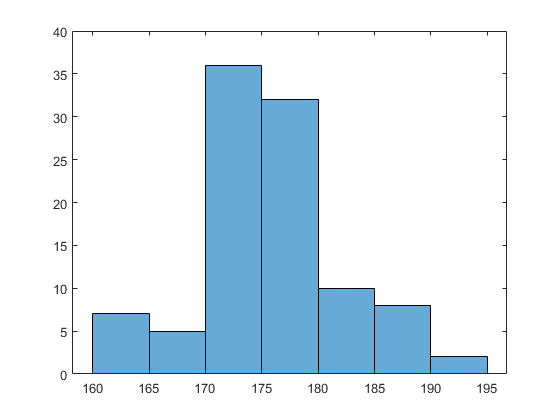

m = 175;
s = 7;
for n = [10, 100, 10000]
    v = m + s * randn(1, 100);
    sprintf('n=%d mean=%f', n, mean(v));
    sprintf('n=%d var=%f' , n, var(v));
    sprintf('n=%d std=%f' , n, std(v));
    histogram(v);
end

### **Úkol 3.    Kovariance nezávislých veličin**

Pro rostoucí N se bude kovariance nezávislých proměnných blížit více a více požadované nule.

x = randn(1, 10);
y = randn(1, 10);
covMatrix = cov(x, y);
sprintf('covarince %f', covMatrix(1, 2))

ans = 'covarince -0.304376'

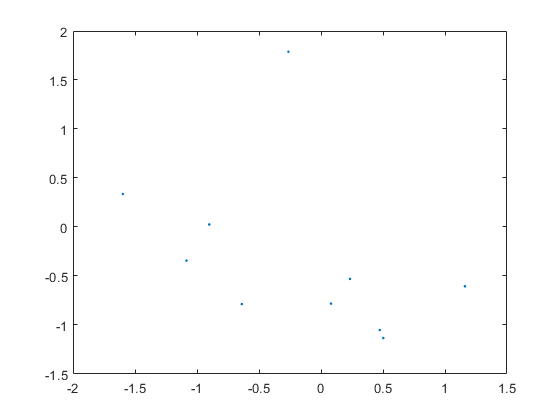

plot(x, y, '.');


x=randn(1, 1000);
y=randn(1, 1000);
covMatrix = cov(x, y);
sprintf('covarince %f', covMatrix(1, 2))

ans = 'covarince 0.018263'

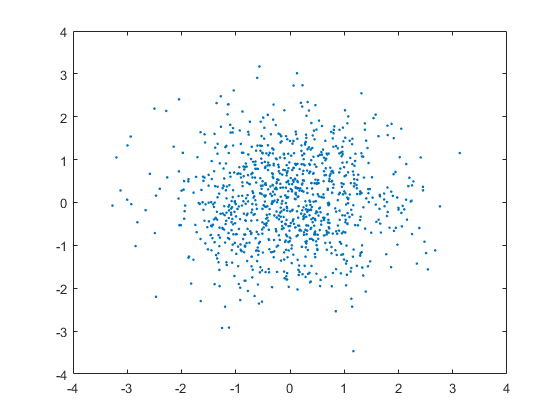

plot(x, y, '.');

### **Úkol 4.    Kovariance závislých veličin**

x = randn(1, 1000); % [m]
y = randn(1, 1000); % [kg]
z = x + y 

z =     2.1656   -0.5471   -1.5403    0.4392    0.5773   -0.7948   -0.3147   -0.7871   -2.6275    2.1861   -1.2307   -0.0655   -0.3616    0.2134   -0.7499    2.0318   -0.4815    0.1504   -3.0242   -2.8003    1.3820    1.6514   -3.7048    1.9620   -0.0536   -0.3726    0.4268    2.5802   -0.4960   -0.8399    0.0108    2.9021   -0.7504    1.6014    0.9585   -2.0277   -0.3751    1.3456    0.7499    0.2950    1.8802    1.5443   -0.7975    0.9268   -0.8006   -0.0322    0.8716   -0.7366   -0.0242    1.3650


covMatrix = cov(x, z);
sprintf('covarince %f', covMatrix(1, 2))

ans = 'covarince 1.007183'

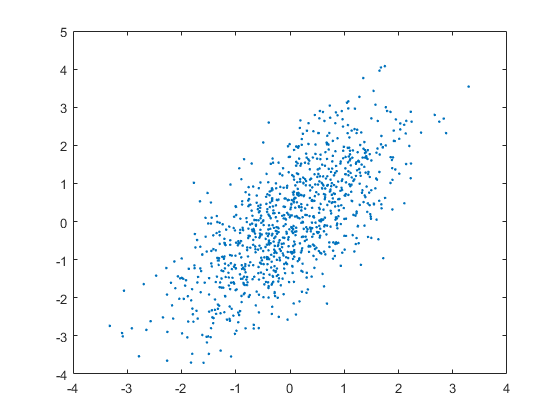

plot(x, z, '.');

Jednotky kovariance jsou $[X] . [Y]$ tedy např. $m . kg$. Při zmenšené/zvětšení (např. m na cm) jedné z jednotek se výsledná jednotka změní poměrně např. stokrát (1m = 100cm). Jak uvidíme dochází k deformaci kruhu/elipsy.

x = randn(1, 1000) * 100; % [cm]
y = randn(1, 1000); % [kg]
z = x + y 

z =    44.5932   28.4645  106.0858  114.5821 -107.6622   26.7281   62.6540   77.2001 -135.5083   20.3212  -14.6818   25.3284   62.9192 -116.1289  -47.7089   35.5765  -68.1152  -82.5821  -60.0681   -2.5549  137.0702  -39.5608  -90.1659    6.1674   21.1381   74.0700   34.3435  -39.2661    9.4464  -70.3409  164.3862   97.6618 -169.5246   21.3313 -199.1566  -34.4739  205.5861  -70.1484  145.2831  -12.2934   33.9151  -43.0830  -79.7112  -10.5127  -16.0965   -6.5326   60.5506   52.4910   75.7588  -82.9912


covMatrix = cov(x, z);
sprintf('covarince %f', covMatrix(1, 2))

ans = 'covarince 10471.624341'

plot(x, z, '.');

### Úkol 5 + 6.  Doplním, nějak nerozumím asi zadání.

- Kontrolní otázka 1: Data zs jsme vyrobili jako vážený průměr z náhodné sekvence. Jak souvisí délka klesání kovariance u počátku s počtem průměrovaných datových hodnot (s počtem vah)?

- Kontrolní otázka 2: Proč je na 9. řádku wma příkaz zs=mean(z)*ones(1,n);? **Vytvoříme si vektor o **$n$** prvcích obsahující **$mean$.

- Kontrolní otázka 3: Jak lze pomocí vhodné volby vah napodobit obr. 6.7 dole?

- Kontrolní otázka 4: Data zs jsme vyrobili jako vážený průměr z náhodné sekvence. Jak souvisí délka stoupání variogramu u počátku s počtem průměrovaných datových hodnot (s počtem vah)

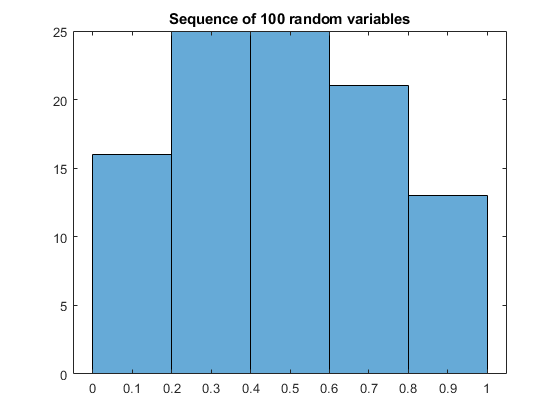

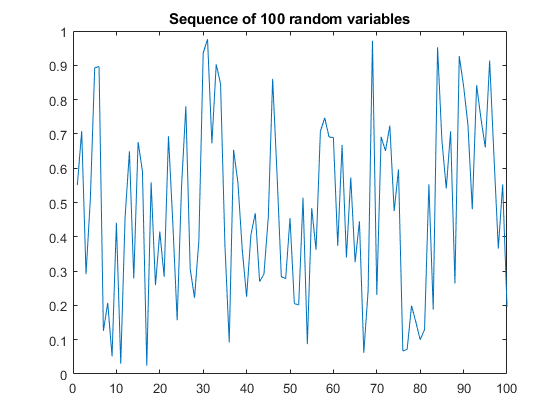

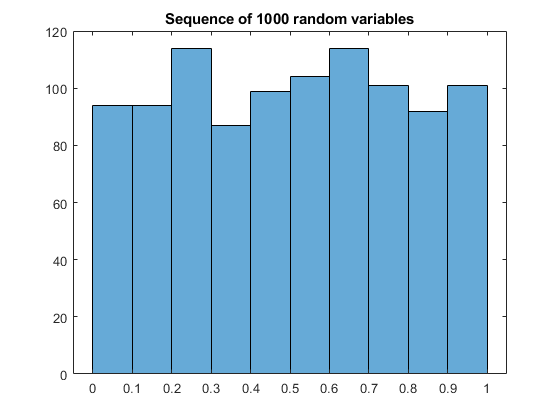

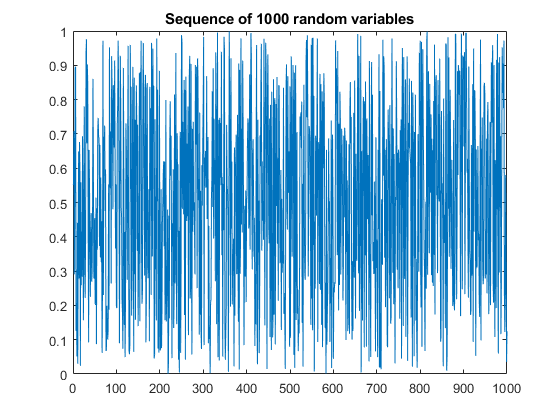

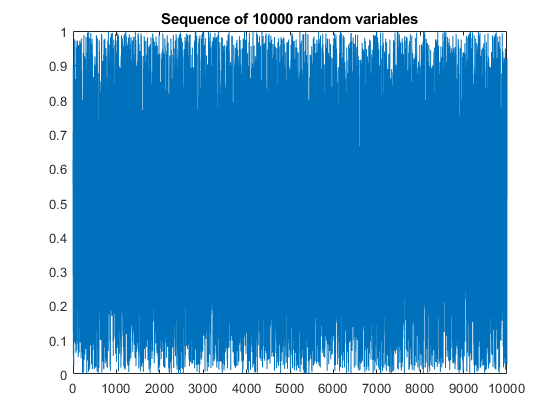

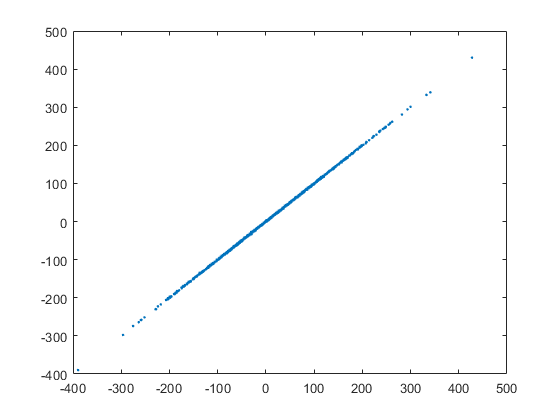

n = 100

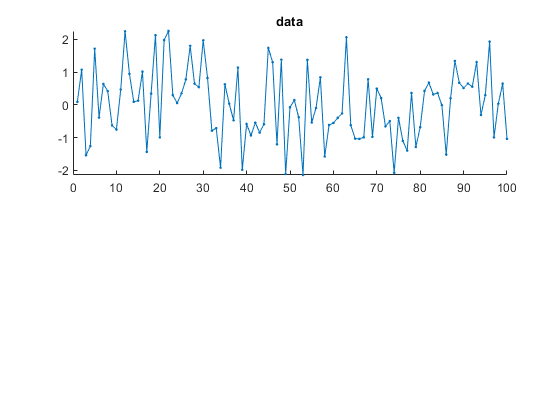

z = randn(1, 100); 
c = kovariance(z, 30);

zs = wma(z,[1 1 1] / 3);
c = kovariance(zs, 30);

### Úkol 7.    Náhodná procházka

**1D Random Walk**

randomWalk1D(50);

**2D Randowm Walk**

randomWalk2D(50);